Aufgabe 7)

3.

clear;
x = rand(1,100) + 1i*rand(1,100);

4.

if (sum(abs(x - idft(dft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


5.

if (sum(abs(x - idft(fft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


if (sum(abs(x - ifft(dft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


if (sum(abs(x - ifft(fft(x)))) < 10e-10)
    disp("Die Singale sind identisch!");
end

Die Singale sind identisch!


6.

tic;
fft(x);
toc;

Elapsed time is 0.002952 seconds.


tic;
dft(x);
toc;

Elapsed time is 0.006569 seconds.


x = rand(1,10000) + 1i*rand(1,10000);
tic;
fft(x);
toc;

Elapsed time is 0.003625 seconds.


tic;
dft(x);
toc;

Elapsed time is 10.136263 seconds.


Aufgabe 8)

f1 = 40;        % [Hz]
f2 = 60;        % [Hz]

t = 0 : 1 / 100 : 2*pi;
x1 = cos(2 .* pi .* f1 .* t);
x2 = cos(2 .* pi .* f2 .* t);

a1 = fft(x1 + x2);
b1 = fft(x1) + fft(x2);
if (sum(real(a1 - b1)) < 10e-10)
    disp("Die Aussage ist wahr!");
end

Die Aussage ist wahr!


if (sum(imag(a1 - b1)) < 10e-10)
    disp("Die Aussage ist wahr!");
end

Die Aussage ist wahr!



x3 = cos(2.*pi.*f1.*(t + (pi ./ 3)));
a2 = fft(x3);

b2 = fft(x1) * exp(1i .* 2 .* pi .* f1 .* (pi ./ 3));

if(sum(real(a2 - b2)) < 10e-10)
    disp("Die Aussage ist wahr!");
end

Die Aussage ist wahr!



if(sum(imag(a2 - b2)) < 10e-10)
    disp("Die Aussage ist wahr!");
end

Aufgabe 9)

1.

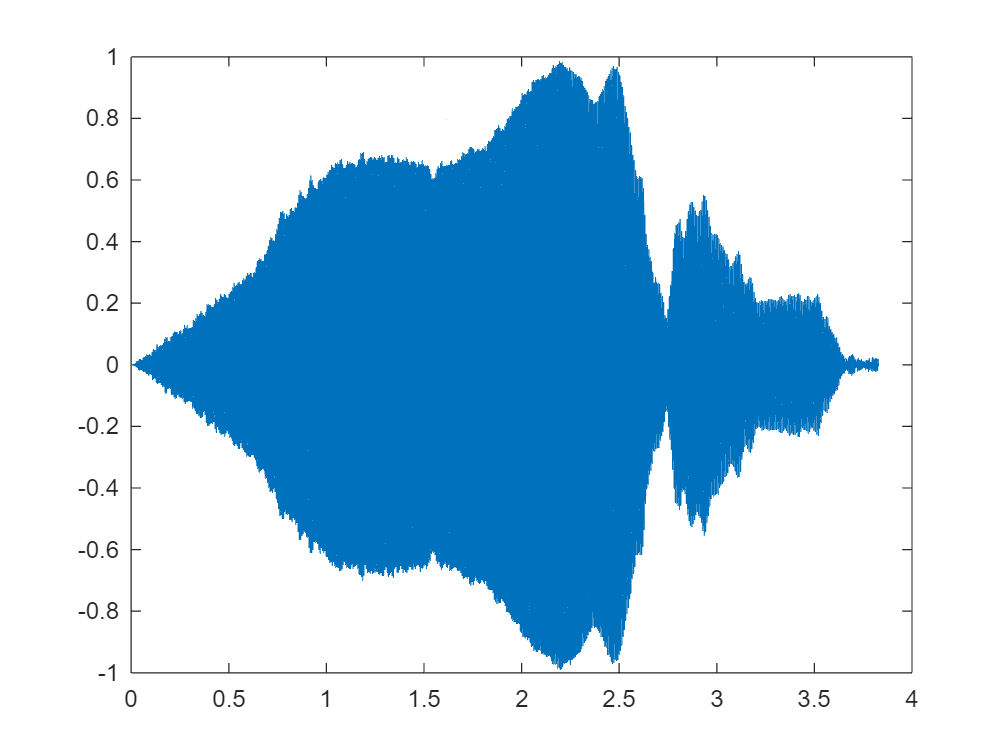

[y,Fs] = audioread("blue2ok1.mp3") ; 
x = (1:length(y)) /Fs ; 
plot(x,y);

2.

sound(y,Fs);

3. 

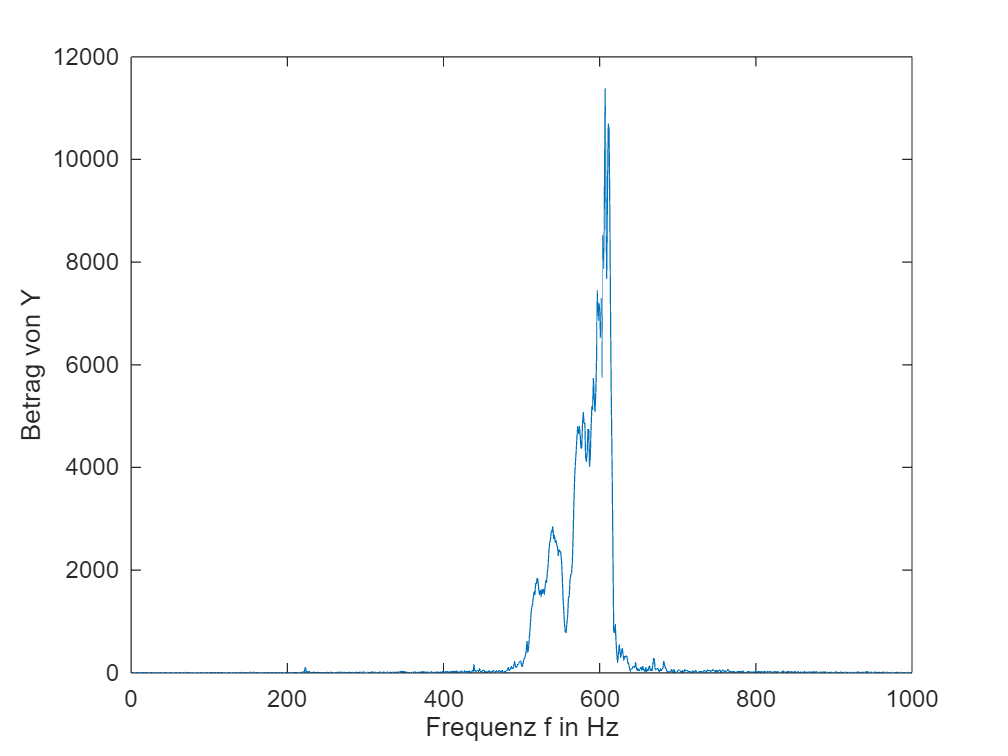

N = length(y);
f = (0 : 1000 - 1)';
Y = fft(y);
Y1 = abs(Y(1:1000,1));
plot(f, Y1);
xlabel("Frequenz f in Hz");
ylabel("Betrag von Y");

[maxValue, maxIndex] = max(Y1);
disp("Die Hauptfrequenzkomponente liegt bei " + (maxIndex - 1) + "Hz.");

Die Hauptfrequenzkomponente liegt bei 607Hz.
